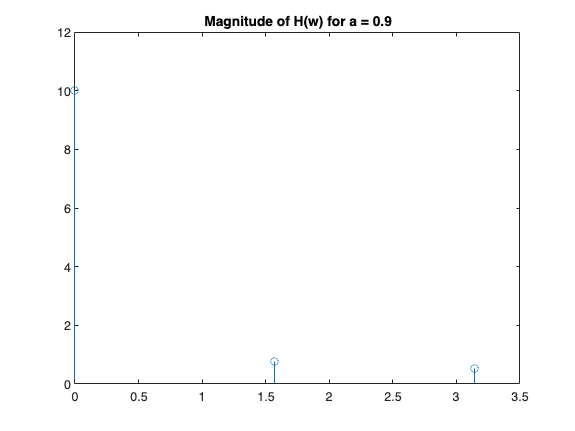

% Problem 2
% Applying the Fourier Transform and isolating 
% Y(w)/X(w), we have H(w) = 1 / (1 - a.exp(-jw))
w = [0 pi/2 pi];
a = 0.9;
H = 1 ./ (1 - a*exp(-j*w));
stem(w, abs(H));
title('Magnitude of H(w) for a = 0.9')

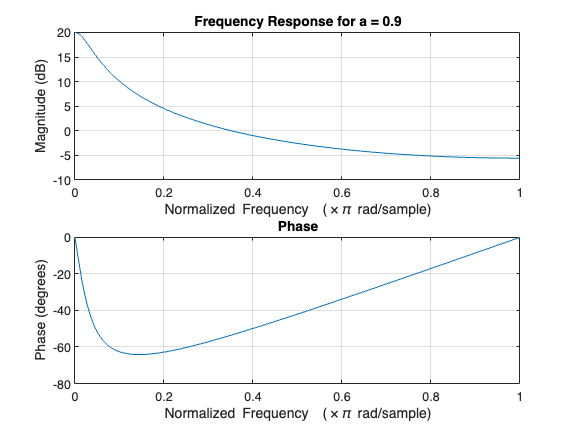


% This is a Low pass, we can also use freqz to
% plot the frequency response, for vector of
% coefficients cb = [1] and ca = [1 -a]
cb = [1];
ca = [1 -a];
freqz(cb,ca)
title('Frequency Response for a = 0.9')


% The sampling frequency Fs when is divided by 2 is
% mapped to pi (pi is the highest discrete frequency
% possible and Fs/2 is the highest frequency component
% that can be sampled with Fs)
%
% Thus if Fs = 1000 Hz, 250 Hz maps to Fs/4 which
% is pi/2, and its magnitude is
H250 = abs(1 / (1 - a*exp(-j*pi/2)))

H250 = 0.7433

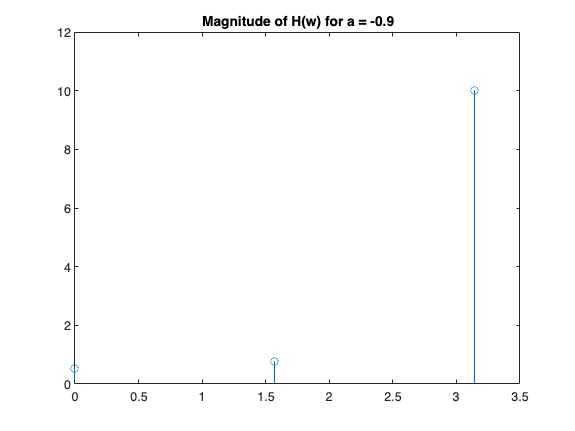


% Repeating for a = -0.9
a = -0.9;

H = 1 ./ (1 - a*exp(-j*w));
stem(w, abs(H));
title('Magnitude of H(w) for a = -0.9')

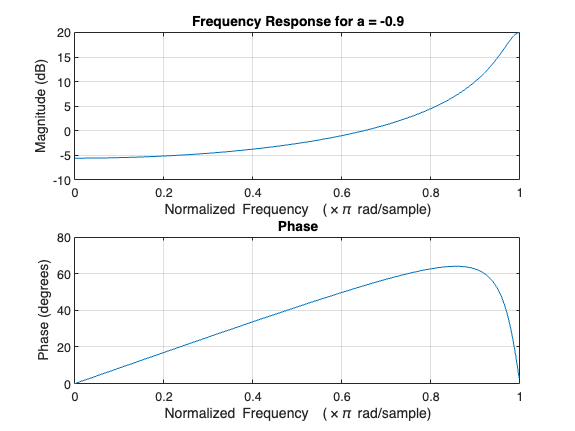


% This is a High pass, we can also use freqz to
% plot the frequency response, for vector of
% coefficients cb = [1] and ca = [1 -a]
cb = [1];
ca = [1 -a];
freqz(cb,ca)
title('Frequency Response for a = -0.9')



H250 = abs(1 / (1 - a*exp(-j*pi/2)))

H250 = 0.7433

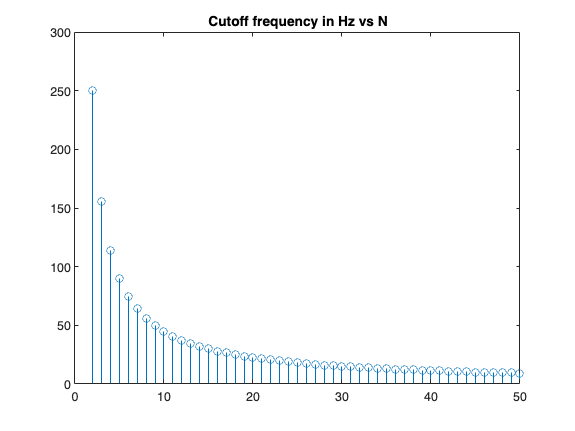


% Problem 3s
%
% part a)
% The moving average filter, given N, will have
% coefficients of the difference equation be
% a = [1] (we do not use any delayed values of
% y(n)) and for b there will be N elements
% whose coefficients are 1/N, so that's how
% we can compute b, a.
%
% For computing wl, H(w) of the moving average
% is H(w) = 1/N *(1 + exp(-jw) + exp(-2jw) + ... + exp(-(N-1)jw))
% We need to find wl such that abs(H(wl))/abs(H(0)) = 1/sqrt(2).
% In order to do that we define the function 
% cutoff = abs(H(w)) - abs(H(0))/sqrt(2) and call fzero on it.
% We use nested functions in Matlab so we can use N
% inside the cutoff function
%
% part b)
%
wl = [];
for N = 2:50
    [b, a, w] = moving_average_filter(N);
    wl = [wl w];
end
stem(2:50, wl/pi*500)
title('Cutoff frequency in Hz vs N')

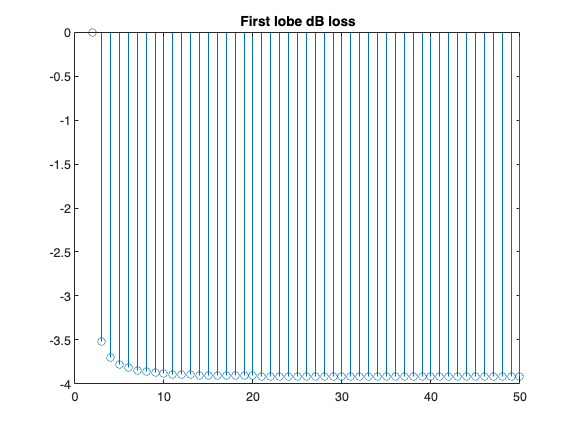


%
% part c
%
% The first zero happens at 2pi/N (from Homework 4
% question 4, part c), and the second zero at 
% is at Nw/2 = 2pi, i.e., w = 4pi/N, we can look for
% the peak between these 2 intervals

dbloss = [];
for N = 2:50
    dw = pi/N:(2*pi/N)/1000:4*pi/N;
    h = moving_filter(dw,N);
    maxh = max(h);
    dbloss = [dbloss 20*log10(maxh)];
end
stem(2:50, dbloss);
title('First lobe dB loss')

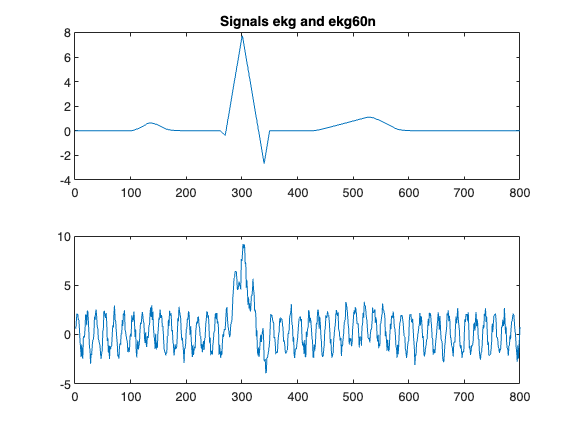

% Problem 4
clear;
load ekg.mat;
% part a
subplot(2,1,1);
plot(ekg);
title('Signals ekg and ekg60n');
subplot(2,1,2);
plot(ekg60n);

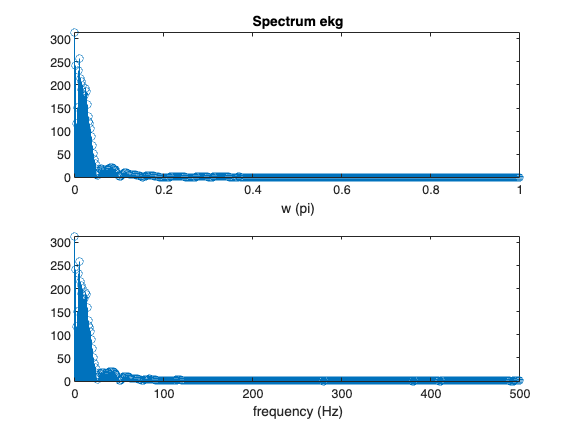

% part b
Fs = 1000;
ekgX = fft(ekg,1024);
lenX = length(ekgX);
w = 0:(pi)/(lenX/2 - 1):pi;
f = 0:(Fs/2)/(lenX/2 - 1):Fs/2;
figure;
subplot(2,1,1);
stem(w/pi, abs(ekgX(1:lenX/2)));
title('Spectrum ekg');
xlabel('w (pi)');
subplot(2,1,2);
stem(f, abs(ekgX(1:lenX/2)));
xlabel('frequency (Hz)');

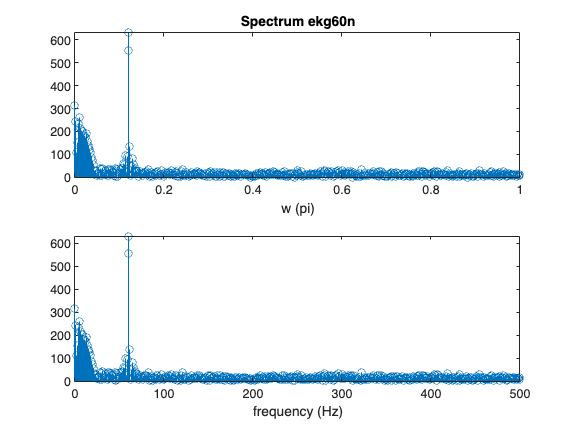


figure;                                                                                        
ekg60nX = fft(ekg60n, 1024);
subplot(2,1,1);
stem(w/pi, abs(ekg60nX(1:lenX/2)));
title('Spectrum ekg60n');
xlabel('w (pi)');
subplot(2,1,2);
stem(f,abs(ekg60nX(1:lenX/2)));
xlabel('frequency (Hz)');

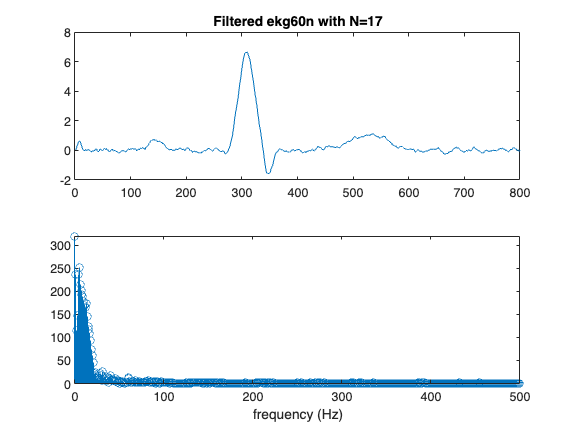


% 60 Hz maps to 60*pi/500, which is 
% 0.377. A zero in the moving frequency
% filter can be set at pi/N. 
[b,a,wl] = moving_average_filter(17);
ekgf = filter(b,a,ekg60n);
ekgfX = fft(ekgf,1024);
figure;
subplot(2,1,1);
plot(ekgf);
title('Filtered ekg60n with N=17');
subplot(2,1,2);
stem(f,abs(ekgfX(1:lenX/2)));
xlabel('frequency (Hz)');

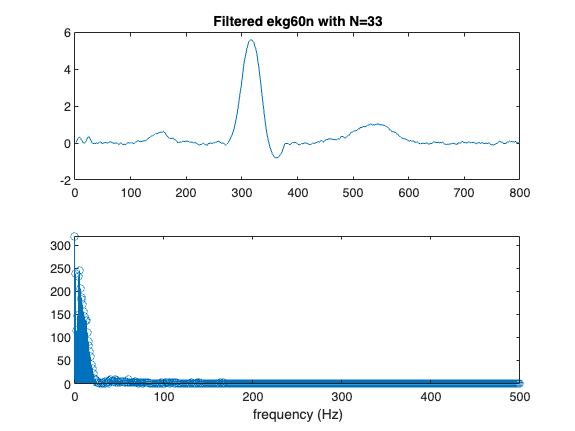

% We see great attenuation of the 60 Hz
% signal but we still see white noise
% present. We can attempt an N in which
% the second 0 tries to approach the 60 Hz,
% that is 4*pi/N = 0.377, with N = 33
[b3,a3,wl] = moving_average_filter(33);
ekg33f = filter(b3,a3,ekg60n);
ekg33fX = fft(ekg33f,1024);
figure;
subplot(2,1,1);
plot(ekg33f);
title('Filtered ekg60n with N=33');
subplot(2,1,2);
stem(f,abs(ekg33fX(1:lenX/2)));
xlabel('frequency (Hz)');

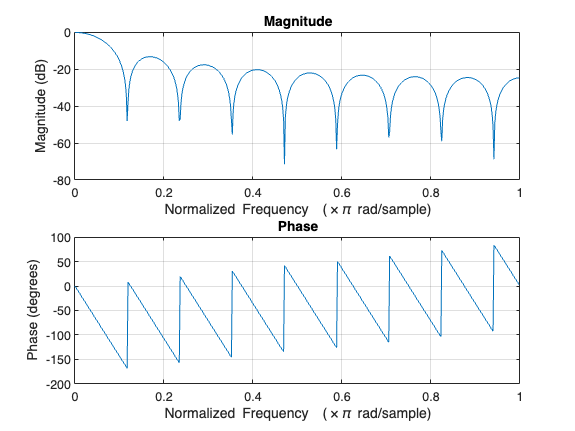


% part d
% We see greater attenuation of the white noise
% as the filter with N = 33 attenuates the spectrum
% overall. The tradeoff is in memory, as we need
% 33 samples in this case
figure;
freqz(b,a);

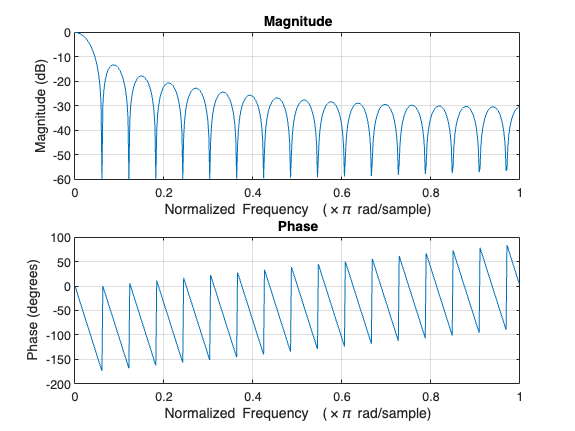

figure;
freqz(b3,a3);

function hw = moving_filter(w,N)
    n = 1:N;
    h = exp(-1i * (w' * (n-1))); % each row has a fixed wf
    hw = abs(sum(h,2)/N); % sum every row (i.e., we end up with a column vector), each row is H(wf)
    hw = hw'; % we return a row vector
end
